# **RT-QIBC analysis**

**FarRed1: EdU**

**YFP1: Cdt1 IF**

**POI(:,3): CRL4Cdt2 activation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    '48 siCtrl dox-',3,11,1:4,[0 0 0],'NR48','Dox-','siCtrl'; %1
    '48 siCtrl dox+',3,2:10,1:4,[0 0 0],'NR48','Dox+','siCtrl'; %1
    
    '48 siGMNN dox-',4,11,1:4,[0 0 0],'NR48','Dox-','siGMNN'; %1
    '48 siGMNN dox+',4,2:10,1:4,[0 0 0],'NR48','Dox+','siGMNN'; %1
     
    '60 siGMNN dox-',5,11,1:4,[0 0 0],'NR60','Dox-','siGMNN'; %1
    '60 siGMNN dox+',5,2:10,1:4,[0 0 0],'NR60','Dox+','siGMNN'; %1
    
    '61 siGMNN dox-',6,11,1:4,[0 0 0],'NR61','Dox-','siGMNN'; %1
    '61 siGMNN dox+',6,2:10,1:4,[0 0 0],'NR61','Dox+','siGMNN'; %1
    
    '62 siGMNN dox-',7,11,1:4,[0 0 0],'NR62','Dox-','siGMNN'; %1
    '62 siGMNN dox+',7,2:10,1:4,[0 0 0],'NR62','Dox+','siGMNN'; %1
    };


load([dataDir filesep 'C167_data.mat'],'S');
%S = loadData_C167(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 72;
frameEdU = 0;
timeStart = 2.1;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

**Set thresholds based on treatment 1**

cond = 1;
figure
xval = 'FarRed1';
yval = 'YFP1';
zval = 'YFP2';

xdata = S(cond).(xval);
ydata = S(cond).(yval) ;
zdata = S(cond).(zval) ;


inds = log2(S(cond).dna) < 19.5 & S(cond).apcNuc(:,end) < 20 & xdata < 200;
xdata = xdata(inds);
ydata = ydata(inds);
zdata = zdata(inds);

% inds = xdata < prctile(xdata,95) & ydata < prctile(ydata,95);
% xdata = xdata(inds);
% ydata = ydata(inds);

EdUThresh = prctile(xdata,[50 95])

EdUThresh =    83.7298  144.1846


HAThresh = prctile(ydata,[50 95])

HAThresh =    11.7323   23.0726


GMNNThresh = prctile(zdata,[50 95])

GMNNThresh =    77.0434  146.9740


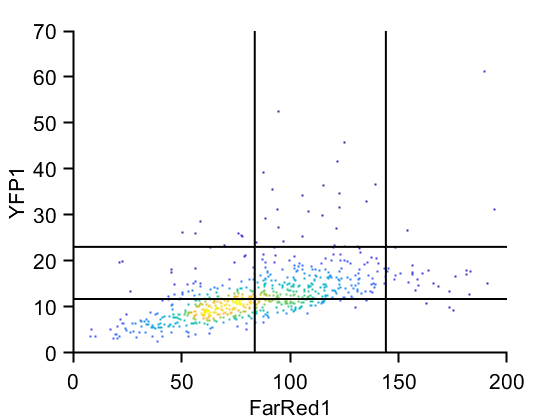



dscatter(xdata,ydata)
hline(HAThresh,'k');
vline(EdUThresh,'k');
ylabel(yval);xlabel(xval);

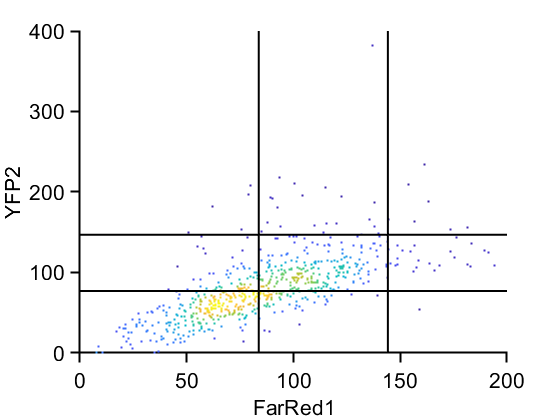


dscatter(xdata,zdata)
hline(GMNNThresh,'k');
vline(EdUThresh,'k');
ylabel(zval);xlabel(xval);

Settings thresholds based on 95% (with a removal of EdU positive cells by arb threshold)

**Dose response Cdt1**

conds=[ 4 6 10];
%conds = [4 10];
poiAligned=3;
offset=0;

colors = lines(3);
%colors = [0 113 188; 193 39 45]/255;
colorval = [1 2 3 ];

range = 3:.5:10.5;
timeGate = [1 2 ];
thresh = log2(EdUThresh);

f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);


for i=1:length(conds)
    ind=~isnan(S(conds(i)).POI(:,poiAligned));
%     ind = S(conds(i)).YFP2 < 200;
    
    tdata=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    gatedata=log2(S(conds(i)).YFP1(ind));
    ydata=log2(S(conds(i)).FarRed1(ind)) ;
    wells = string(num2str(S(conds(i)).wellindex(:,1:2)));
    
    inds = tdata >= timeGate(1) & tdata <= timeGate(2);
    tdata = tdata(inds);
    ydata = ydata(inds);
    gatedata = gatedata(inds);
    wells = wells(inds);
    
    stand =  nanmean(ydata(gatedata <= 5 & gatedata >= 4));
    stand = 0;
    ydata = ydata -stand;
    
    threshs ={{thresh(2) - stand, 1}};
    [binData, edges] = bin_xy(gatedata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',range);
    edges = edges(1:end-1);
    midpoints = edges + (edges(2) -edges(1))/2;

    
    figure(f1)
    hold on
    %dscatter(ydata2,ydata3);
    errorbar(midpoints, binData.mean, 2*binData.sem,'.-','LineWidth',1.5,'Color',colors(colorval(i),:))
    %scatter(xInd,meanInd,'o','MarkerEdgeColor',colors(colorval(i),:),'LineWidth',1.5);
    %scatter(gatedata,ydata,'.');
 
    fprintf('Cond %d, min cells in bin: %d',i,min(binData.numCells))
    fprintf('Cond %d, total cells: %d',i,length(ydata))
    
%     output = [xInd' meanInd'];
end

Cond 1, min cells in bin: 37

Cond 1, total cells: 1048

Cond 2, min cells in bin: 26

Cond 2, total cells: 1065

Cond 3, min cells in bin: 32

Cond 3, total cells: 1124

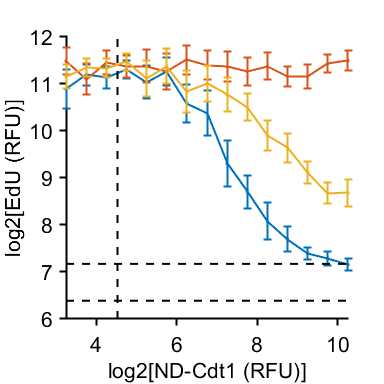

   xlabel('log2[ND-Cdt1 (RFU)]');
    ylabel('log2[EdU (RFU)]');    
    h=hline(thresh - stand,'k--');
    vline(log2(HAThresh(2)),'k--')
%     xlim([3 11]);
    axis square

%     ylim([-6 1])
%     legend(conditions(conds,1));
% set(gca,'FontSize',16)
print_pdf([pwd() '\Figs\cdt1_dose_response_sem_unnormal.pdf'])